# **Computer Vision no MATLAB (Onramp)**

#### Operações com frames de vídeo

Os códigos abaixo permitem a leitura de um arquivo de vídeo

turtleVideo = VideoReader("turtles.avi"); %Coloca em um formato analisável

Error using VideoReader/initReader (line 734)
The filename specified was not found in the MATLAB path.

Error in audiovideo.internal.IVideoReader (line 136)
            initReader(obj, fileName, currentTime);

Error in 

frame = readFrame(turtleVideo); %Lê o primeiro frame do video
imshow(frame) %Mostra a imagem gerada em frame

O `turtleVideo `tem o formato de "vídeo" em *stop-motion* com inúmeras propriedades. Uma delas é o tempo do frame que está lendo, que pode ser acessado por `turtleVideo.CurrentTime`. Tal número é perfeitamente manipulável, como no código a seguir:

turtleVideo.CurrentTime = 12;
frame2 = readFrame(turtleVideo)

Nesse caso, `frame2` é o frame lido no tempo definido anteriormente. Quando se executa um `readFrame`, o vídeo avança um frame. Ao usar o comando `read(v,n)`, ele lê o *n-ésimo *frame, onde *n *é inteiro.

O último pode ser acessado usando `Inf. `Perceba que ao executar o último frame, não há mais para ler no vídeo, executar um `readFrame `devolve um erro.

frameLast = read(turtleVideo,Inf); %Mostra o último frame
timeLast = turtleVideo.CurrentTime; 

Um passo importante na detecção de imagens é recortar o que você quer que seja identificado. No caso, pode-se usar a seguinte função `imcrop(im,[xmin ymin width height])`

turtleImg = imcrop(frame,[0 170 250 100]) 
imshow(turtleImg) %Mostra a imagem recortada

Pode ser interessante transformar uma imagem em escala de cinza para comparação, usa-se o comando `im2gray`. 

#### Detecção e Extração de *features*

A identificação de características de um objeto da imagem consiste de duas partes distintas: detecção e extração. Para detectar um *blob, *faz-se `detectSIFTFeatures. `A sua saída é um conjunto de pontos de interesse onde ***scale-invariant feature transform (SIFT) ****features *são localizadas. 

**Obs. **SIFT é um algoritmo de visão computacional que descreve pontos chave de forma invariante à rotação, escala, iluminação e perspectiva, ou seja, um *blob* característico de uma imagem pode ser reconhecido em outra, apesar de rotações, escalamentos, mudanças de iluminação e perspectiva.

turtleVideo = videoReader("turtles.avi");
frame = readFrame(turtleVideo); %Leitura do primeiro frame

turtleImg = imcrop(frame,[0 170 250 100]) %Recorte da tartaruga do frame

frameGS = im2gray(frame); 
turtleGS = im2gray(turtleImg);

Agora se usa as funções vistas na seção:

pointsT = detectSIFTFeatures(turtleGS) %Detecção de features pelo SIFT
[featuresT,featurePointsT] = extractFeatures(turtleGS,pointsT)

pointsF = detectSIFTFeatures(frameGS); %Detecção de features pelo SIFT
[featuresF,featurePointsF] = extractFeatures(frameGS,pointsF);

A função `extractFeatures` recebe como entrada a imagem e o conjunto de pontos gerados pelo algoritmo e devolve dois arrays, o `features` e o `featurePoints`.

Agora se faz uma comparação das características tanto da imagem quanto do recorte pela função:

pairs = matchFeatures(featuresT,featuresF)

A saída é uma matriz de duas colunas que contém os índices das *features* que combinaram. A primeira coluna é o conjunto de índices de `featuresT` e a segunda coluna tem índices de `featuresF`.

idxT = pairs(:,1) %Coluna de índices de featuresT
matchedPointsT = featurePointsT(idxT); %Índices de featuresT que combinam

idxF = pairs(:,2) %Coluna de índices de featuresF
matchedPointsF = featurePointsF(idxF); %Índices de featuresF que combinam

A partir de agora, têm se os pontos que combinam de ambas as imagens, que no nosso caso, são relativos à tartaruga. Pode-se fazer uma comparação das duas pela função:

showMatchedFeatures(frame,turtle,matchedPointsF,matchedPointsT,"montage")

Que tem a sintaxe `showMatchedFeatures(im1,im2,...,pts1,pts2,...,"montage")` no qual `pts1,pts2,...` correspondem aos *matched points *das imagens `im1,im2,...`.

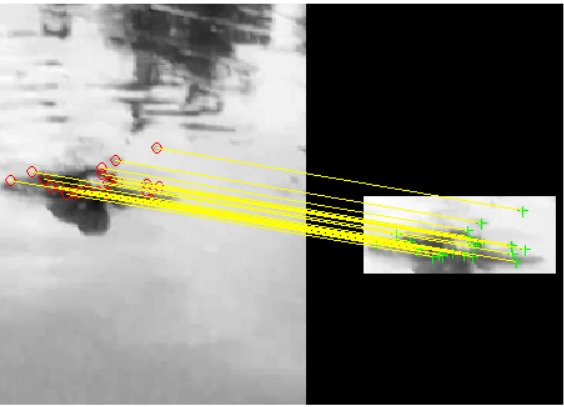

Pode-se mostrar as *features *reconhecidas na imagem original (e no recorte se mudar o *frame*) pelo código:

imshow(frame)
hold on
plot(featurePointsF)
hold off

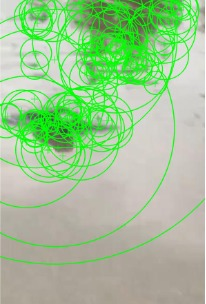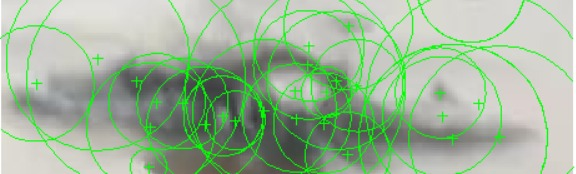

#### Matching de *features*

Um passo em seguida é correlacionar dois frames diferentes, o que pode ser feito por:

turtleVideo = VideoReader("turtles.avi");
frame1 = read(turtleVideo,1);

turtle = imcrop(frame1,[0 170 250 100]);
turtleGS = im2gray(turtle);

frameNum = 37

frame = read(turtleVideo,frameNum);
frameGS = im2gray(frame);

pointsT = detectSIFTFeatures(turtleGS);
[featuresT,featurePointsT] = extractFeatures(turtleGS,pointsT);

pointsF = detectSIFTFeatures(frameGS);
[featuresF,featurePointsF] = extractFeatures(frameGS,pointsF);

pairs = matchFeatures(featuresT,featuresF);

idxT = pairs(:,1);
matchedPointsT = featurePointsT(idxT);

matchedPointsF = featurePointsF(pairs(:,2));

showMatchedFeatures(turtleGS,frameGS, ...
    matchedPointsT,matchedPointsF, ...
    "montage")
imshowpair(frame1,frame) %Mostra as imagens sobrepostas e suas diferenças

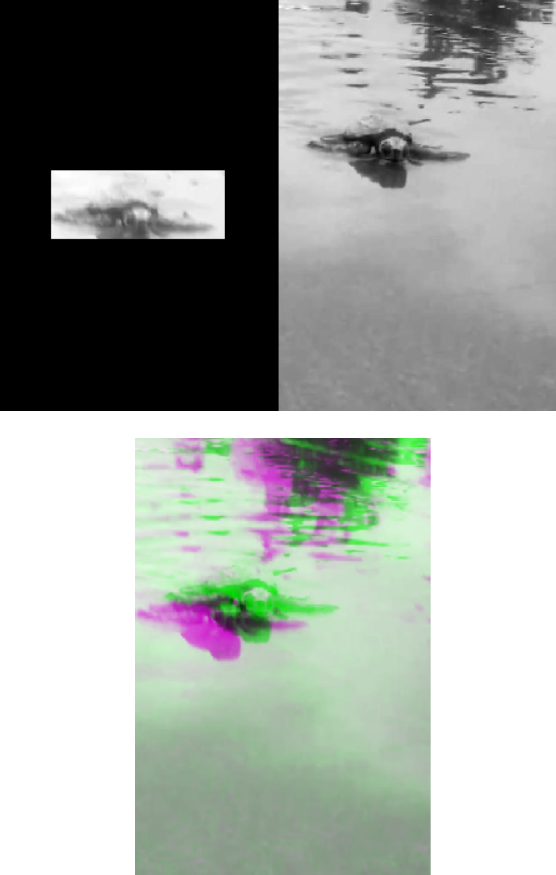

#### Preparação de Ground Truth Data

À medida que o tempo vai passando, a tartaruga muda de posição e de vista. Menos e menos a função de *matching *consegue distinguir que ambas são o mesmo objeto procurado. Utiliza-se um **modelo geral **com generalizações para amplificar a capacidade de reconhecer as tartarugas.

Um modelo precisa de 1) Imagens, 2) Locais e 3) Rótulos. Tal conjunto é chamado **ground truth data**. A partir dele, pode-se treinar um detetor por machine learning ou deep learning

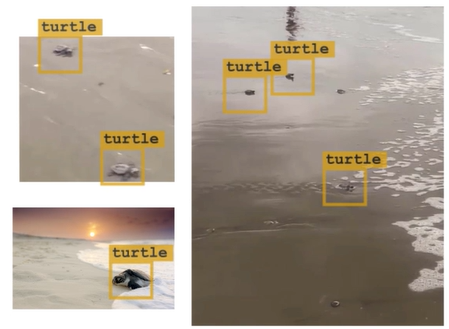

Um bom candidato é um recorte de um vídeo que possui vários frames. Usa-se o app **Video Labeler **do Toolbox de Processamento de Imagens e Visão Computacional. 

- Insere-se o vídeo (*Imagens*)

- Rotula-se as tartarugas por **ROI** (Region of Interest) Label (*Rótulos*)

- Recorta-se manualmente as regiões onde há tartarugas (*Locais*)

A partir daí deve-se recortar frame a frame para haver boa detecção... Mas claro que não precisa ser feito manualmente.

De um frame inicial, escolhe-se um algoritmo para automatizar a detecção.

- Um **interpolador temporal **detecta objetos que se movem em linha reta em velocidade constante, para um objeto só

- O **point tracker **pode detectar múltiplos objetos que não se movem em linha reta pelo algoritmo KLT (Kanade-Lucas-Tomasi)

É interessante após a ação do algoritmo verificar e corrigir possíveis desvios de ROI. 

A partir do instante, o **GTD **pode ser exportado para o MATLAB para ser utilizado com matching de features.

load lotsOturtles_groundTruth.mat %Carrega gTruth
gTruth %Carrega o Ground Truth Data advindo do Video Labeler

No caso, `gTruth `possui três componentes, `DataSource, LabelDefinition `e `LabelData`. Pode-se acessá-los por 

data = gTruth.LabelData %Extração de data de gTruth
bboxes = data.turtle %Dados das caixas
bboxes12 = bboxes{12} %Obtenção da matriz correspondente ao index 12

Tal é uma tabela temporal, onde uma coluna indica os tempos de frames e no outro as caixas de recorte das tartarugas. Foi dado, no app, o *label *com o nome de `turtle` às caixas, para acessá-las da tabela, pode-se usar o ponto e indicar o seu nome. Ou seja, `tbl.VarName`. 

`bboxes12` é uma matriz que indica as caixas detectadas no index `12. `A sua estrutura define todas as caixas e seus tamanhos.

Pode-se assim identificar a posição e tamanho aparente delas. Os valores são medidos a partir do canto superior esquerdo da imagem total.

Também é possível desenhar manualmente usando a função `insertObjectAnnotation(im,... shape,pos,label);` No caso em que `shape = "rectangle"`, `pos` é um vetor de quatro elementos que descreve `[xmin ymin width height]`. Caso `pos` seja uma matriz, cada linha é um quadrado separado.

frameBox = insertObjectAnnotation(frame12,"rectangle",bboxes12,"Turtle");
imshow(frameBox)
xlim([50 175]) %Para visualizar melhor
ylim([425 500])

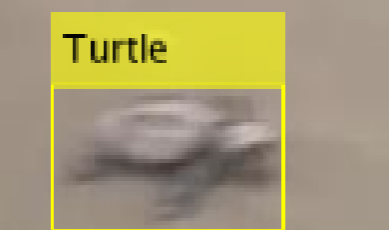

#### Criando imagens de treinamento

O comando `dir `retorna uma lista de arquivos `.png` na pasta selecionada. Pode-se criar imagens de treino de um vídeo usando `objectDetectorTrainingData(gTruth,SamplingFactor=n)`. Tal função escreve cada frame do vídeo em uma imagem, descartando frames sem detecção. Tal sintaxe extrai cada *n-ésimo *frame pelo uso do argumento `SamplingFactor.` O primeiro output são as imagens criadas, o segundo são os *labels*.

load lotsOturtles_groundTruth.mat
gTruth

[imList,boxLabels] = objectDetectorTrainingData(gTruth,SamplingFactor=10)

%This code checks for png files.
dir *.png

Agora o diretório possui um certo número de imagens. A variável

files = imList.Files

Retorna os caminhos das imagens do diretório. Ao adicionar parâmetros no `objectDetectorTrainingData`, pode-se mudar a organização das imagens. 4

[imList,boxLabels] = objectDetectorTrainingData(gTruth,SamplingFactor=10, ...
NamePrefix="turtleFrame",WriteLocation="trainingImages")

imsWithBoxLabels = combine(imList,boxLabels)

As imagens não mudam, mas os diretórios e seus nomes, sim.4

Ao treinar um detetor, é preciso combinar a lista de imagens e rótulos de caixas em uma variável só. Para isso, se usa `combine(ims,labs)`.

Pode-se ver as imagens que vão ser usadas para treino pelo código:

im = imread(files{1});
bb = boxLabels.LabelData{1,1}
im = insertObjectAnnotation(im,"rectangle",bb,"Turtle");
imshow(im)

im2 = imread(files{2});
bb2 = boxLabels.LabelData{2,1}
im2 = insertObjectAnnotation(im2,"rectangle",bb2,"Turtle");
imshow(im2)

im3 = imread(files{3});
bb3 = boxLabels.LabelData{3,1}
im3 = insertObjectAnnotation(im3,"rectangle",bb3,"Turtle");
imshow(im3)

im4 = imread(files{4});
bb4 = boxLabels.LabelData{4,1}
im4 = insertObjectAnnotation(im4,"rectangle",bb4,"Turtle");
imshow(im4)

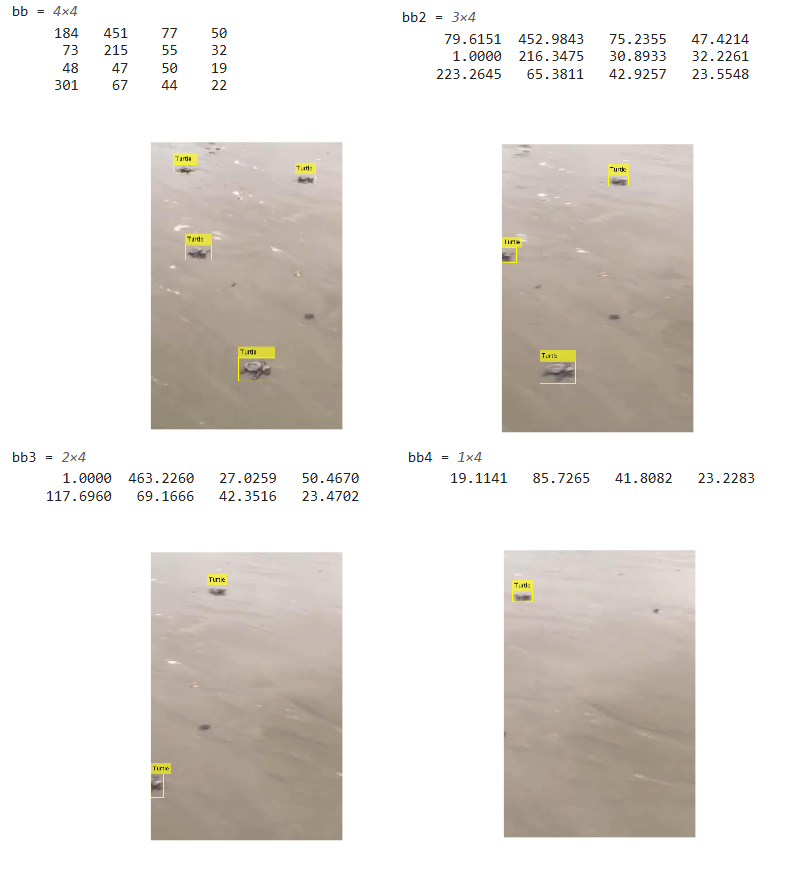

#### Escolha de Algoritmo de Detecção

Agora temos nossa *Ground Truth Data*, então é tempo de treinar a máquina. Pode-se escolher **Machine Learning** ou **Deep Learning**. Devemos nos preocupar somente com fatores como Tempo, Memória e Acurácia dos métodos. É de boa prática ter variabilidade nas imagens que vão ser usadas no treino.

- Machine Learning detecta uma classe por vez, é mais rápida e requer menos dados. Porém é menos precisa, principalmente após mudanças de perspectiva.

- Deep Learning pode detectar várias classes, é mais demorada para treinar e detectar e precisa de mais dados e GPU.

Lembre-se, processamento de imagem pode salvar o processamento.

No caso das tartarugas, uma vez que elas apontam quase sempre na mesma direção, têm a mesma cor e tudo o mais, o melhor se torna Machine Learning. Um ACF (Aggregated Channel Feature) é um algoritmo rápido de detecção e funciona bem onde objetos não mudam significativamente.

Lembremos do último código executado. Podemos treinar um ACF usando a função `trainACFObjectDetector(imsWithLabels) `após executar o combine

...
imsWithBoxLabels = combine(imList,boxLabels)

detector = trainACFObjectDetector(imsWithBoxLabels)

Ele vai retornar algo parecido com isso:

`ACF Object Detector Training`

`The training will take 4 stages. The model size is 15x27.`

`Sample positive examples(~100% Completed)`

`Compute approximation coefficients...Completed.`

`Compute aggregated channel features...Completed.`

`--------------------------------------------`

`Stage 1:`

`Sample negative examples(~100% Completed)`

`Compute aggregated channel features...Completed.`

`Train classifier with 10 positive examples and 50 negative examples...Completed.`

`The trained classifier has 19 weak learners.`

`--------------------------------------------`

`Stage 2:`

`Sample negative examples(~100% Completed)`

`Found 20 new negative examples for training.`

`Compute aggregated channel features...Completed.`

`Train classifier with 10 positive examples and 50 negative examples...Completed.`

`The trained classifier has 19 weak learners.`

`--------------------------------------------`

`Stage 3:`

`Sample negative examples(~100% Completed)`

`Found 19 new negative examples for training.`

`Compute aggregated channel features...Completed.`

`Train classifier with 10 positive examples and 50 negative examples...Completed.`

`The trained classifier has 19 weak learners.`

`--------------------------------------------`

`Stage 4:`

`Sample negative examples(~100% Completed)`

`Found 5 new negative examples for training.`

`Compute aggregated channel features...Completed.`

`Train classifier with 10 positive examples and 50 negative examples...Completed.`

`The trained classifier has 19 weak learners.`

`--------------------------------------------`

`ACF object detector training is completed. Elapsed time is 1.1032 seconds.`

Pode-se aplicar então o detector criado pela função `detect(detector,im) = [b,s].` A primeira saída é uma matriz de *bounding boxes* identificando os objetos na imagem. Já a segunda é matriz de *confidence scores* indicando o nível de confiança na detecção.

[bbox,score] = detect(detector,frame)

%Criação da imagem com as zonas de detecção
frameLabeled = insertObjectAnnotation(frame,"rectangle",bbox,score)
imshow(frameLabeled) 

%Lembrete: imNew = insertObjectAnnotation(im,shape,pos,label)

Da mesma forma que as *ground truth values*, as *bounding boxes* são armazenadas em linhas que indicam `xmin, ymin, width, heigh`. O que vai aparecer será uma imagem com pontuais acumulações de *bounding boxes *de inúmeras detecções feitas pelo ACF.

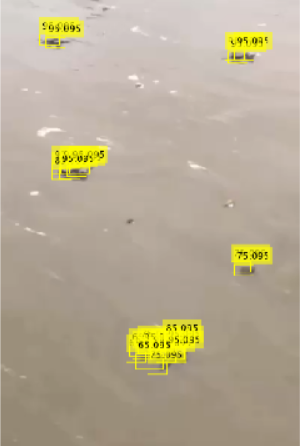

Perceba que uma pedra foi detectada como uma tartaruga. Pode-se aumentar a precisão do detetor no seu treinamento pelo parâmetro `NumStages`:

detector = trainACFObjectDetector(imsWithBoxLabels, NumStages=5)

#### Como melhorar a performance do detetor

[imList,boxLabels] = objectDetectorTrainingData(gTruth, ...
    SamplingFactor=4, ...
    WriteLocation="trainingImages", ...
    NamePrefix="turtleFrame");
imsWithBoxLabels = combine(imList,boxLabels);

Mudar o `SamplingFactor` para 4 aumenta o número de imagens usadas no treino do detetor. Ao invés de pegar uma imagem a cada 10 segundos, ele passa a pegar a partir de 4.

detector = trainACFObjectDetector(imsWithBoxLabels, NumStages=5)
[bbox,score] = detect(detector,frame);

frameLabeled = insertObjectAnnotation(frame,"rectangle",bbox,score);
imshow(frameLabeled)

Com o aumento do número de imagens, a detecção fica mais lenta, porém mais precisa.

#### Processamento Pós-Detecção

Em uma imagem com muitas *bounding boxes*, faz mais sentido manter a que possui maior confiança.

...
[bbox,score] = detect(detector,laterFrame);
img = insertObjectAnnotation(laterFrame,"rectangle",bbox,score);
imshow(img)

xlim([0 200])
ylim([0 300])

Pode-se remover as caixas de menor confiança estabelecendo um limite. Um limite pode ser melhor visualizado fazendo um histograma. Tal usa a função `histogram(vec,NumBins)`

histogram(score,10) %Retorna um histograma mostrando as porcentagens e 
% distribuição

bbox = bbox(score>30,:); %Filtro dos bounded boxes para mais de 0.3
score = score(score>30) %Filtro dos scores para mais de 0.3 de confiança

 É bem possível que um filtro mais alto elimine uma *bbox* de alguma tartaruga, mas deixa duplicado uma detecção a uma tartaruga. Usa-se a função

`selectStrongestBox(bbox, score, OverlapThreshold = thresh)`

Onde `thresh `é um parâmetro entre [0,1]. Tal parâmetro indica para a função remover quaisquer caixas que se sobreponham com raio acima do limite definido pelo `thresh`. 

[selectedBbox,selectedScore] = selectStrongestBbox(bbox,score,...
OverlapThreshold=0.2) %Definição do novo conjunto de bounded boxes
% selecionadas

img2 = insertObjectAnnotation(laterFrame,"rectangle",selectedBbox,...
selectedScore)
imshow(img2)

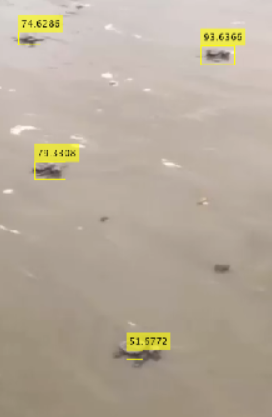

#### Contagem de Detecção

A contagem de elementos detectados é útil no monitoramento de um tipo de população. Pode-se contar a quantidade de tartarugas vistas em uma imagem e anotar tal número. Vamos usar a função `size(M,1)` para contar a quantidade de linhas de `M`.

...
%Detecção
[bbox,score] = detect(detector,laterFrame); 

%Filtragem probabilística
bbox = bbox(score>30,:);
score = score(score>30);

%Filtragem de sobreposição
[selectedBbox,selectedScore] = selectStrongestBbox(bbox,score, ...
OverlapThreshold=0.1);

%Obtenção da imagem com detecção tratada
img = insertObjectAnnotation(laterFrame,"rectangle", ...
selectedBbox,selectedScore);

imshow(img)

O que queremos é o número de imagens. Podemos então criar uma string com o número ditado na imagem e até anotar na imagem o string criado pela função `imNew = insertText(im,[xmin ymin],textStr). `O parâmetro `FontSize `é interessante para mudar o tamanho da letra. Ele também pode ser usado no `insertObjectAnnotation`.

numBoxes = size(selectedBbox,1)

%Criação do String
str = numBoxes + " turtle(s) detected";

%Anotação na imagem cria outra com o texto
imgCounted = insertText(img,[250 550],str,FontSize=24);
imshow(imgCounted);

#### Detectando objetos em cada frame

Ao ler todos os frames de um vídeo, é importante ter um ponto de stop, quando os frames acabam, antes de obter um big erro.

turtleVideo = VideoReader("lotsOturtles_firstSec.avi");
frame = read(turtleVideo,28);
imshow(frame)
turtleVideo.CurrentTime

Pode-se usar uma função que diz simplesmente se ainda há frames para usar

yesNo = hasFrame(turtleVideo)
if yesNo == 1
    img = readFrame(turtleVideo);
    imshow(img);
end

Em um código, usa-se `drawnow` para compilar as imagens vistas frame a frame em um vídeo

while hasFrame(turtleVideo) == 1
    frame = readFrame(turtleVideo);
    [bbox,score] = detect(detector,frame);
    bbox = bbox(score>30,:);
    score = score(score>30);
    [selectedBbox,selectedScore] = selectStrongestBbox(bbox,score, ...
        OverlapThreshold=0.1);
     
    
    numBoxes = size(selectedBbox,1);
    str = numBoxes + " turtle(s) detected";
    img = insertObjectAnnotation(frame,"rectangle", ...
        selectedBbox,"Turtle: " + selectedScore);
    img = insertText(img,[250 550],str,TextColor=[1 1 0]);
    imshow(img)
    drawnow
end    

#### Tracking usando Filtro de Kalman

Um objeto pode ser visto e acompanhado por detecção de objetos integrado com um Filtro de Kalman. Sem um artifiício assim, um objeto bloqueado ou fora de vista momentaneamente se torna algo novo para a máquina, diferentemente do nosso entendimento. Existem algumas suposições sobre o acompanhamento do objeto, como **Posição, Velocidade, Aceleração, Erro **e **Ruído**. 

O **Filtro de Kalman **implementa um processo de Predição, Detecção e Correção.

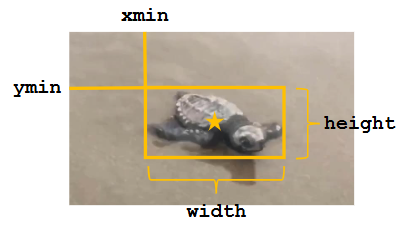

Primeiro, vamos achar uma forma de encontrar o centróide dessa figura.

Uma forma de achar o centro da figura detectada é fazendo:


$$x_{\mathrm{center}} =x_{\min } +\mathrm{width}\cdot 0\ldotp 5$$



$$y_{\mathrm{center}} =x_{\min } +\mathrm{height}\cdot 0\ldotp 5$$


load ACFdetector4tracking
turtleVideo = VideoReader("turtle.avi");
frame = readFrame(turtleVideo);
[bbox,score] = detect(detector,frame);
bbox = bbox(score>95,:);
score = score(score>95);
bbox = selectStrongestBbox(bbox,score, ...
    NumStrongest=1);

%Centróide do boundedbox
xcenter = bbox(1) + 0.5*bbox(3)
ycenter = bbox(2) + 0.5*bbox(4)
centroid = [xcenter ycenter]

Devemos inserir um símbolo para visualizar o centróide nos frames do vídeo, para tal:

`imNew = insertShape(im,shape,pos,Name=Value);`

A variável `pos `tem três elementos, `xCenter yCenter radius`. Já o parâmetro `shape` pode ser `"circle", "filled-circle",...`

frame = insertShape(frame,"filled-circle",[centroid 50],Color="green");
imshow(frame);

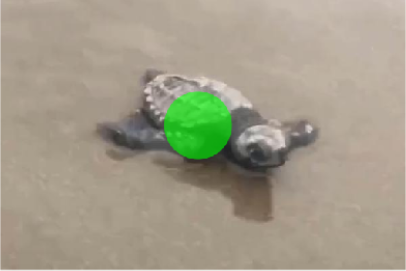

Note que o código não roda a parte do centróide a partir do frame em que o detetor não vê mais a tartaruga. Agora vamos iniciar a implementação do Filtro de Kalman.

Primeiro criamos uma string que define o modelo de movimentação da Tartaruga.

motionModel = "ConstantVelocity"

Então devemos definir uma posição inicial onde o Filtro vai começar a atuar, tal é vista pelo detetor e computada em `centroid`.

initialLoc = centroid

Estimamos o **ruído** causado por fatores adversos da gravação ou deteção, pois as *bounding boxes* variam de posição com o algoritmo ao longo dos frames. Tal ruído é uma *variância*. Se o centróide muda de posição em torno de 10 pixels, pode-se usar 10^2 = 100 como parâmetro de ruído.

measurementNoise = 100

Existe um balanço entre detecção e modelo de movimento. Um ruído maior implica que o filtro de Kalman vai depender mais da detecção. Um ruído de movimento de velocidade constante tem a forma de um vetor de dois elementos `[LocationVariance VelocityVariance]`. Estimamos os desvios de localização e velocidade como 1 pixel e 5 px/s. Eleva-se ambos ao quadrado.

motionNoise = [1 25]

A velocidade inicial do filtro é assumida ser zero. Provenha-o com um erro inicial para que se ajuste após algumas detecções. O erro incial também é um vetor de dois elementos de variância. Os valores do erro incial afetam somente os frames inciais de detecção.

initialError = [1 25]

Para inicializar o filtro usa-se a estrutura:

`kalmanFilter = configureKalmanFilter(MotionModel, Initial Location, InitialEstimateError, MotionNoise, MeasurementNoise)`

kf = configureKalmanFilter(motionModel, initialLoc, initialError, ...
motionNoise, measurementNoise)

Obs. Para mais de uma tartaruga, é preciso configurar mais de um Filtro de Kalman. Pode-se usar o `Mutiple Object Tracking` e `Sensor Fusion and Tracking Toolbox.`

Agora faremos o Filtro funcionar usando a função `trackedLocation = predict(KalmanFilter)`. Ela prevê onde a tartaruga vai estar no frame seguinte.

trackedLoc = predict(kf)

O próximo frame é detectado pelo código

frame = readFrame(turtleVideo);
[bbox,score] = detect(detector,frame);
bbox = bbox(score>95,:);
score = score(score>95);
strongestBbox = selectStrongestBbox(bbox,score,NumStrongest=1);
centroid = [strongestBbox(1)+strongestBbox(3)/2  strongestBbox(2)+strongestBbox(4)/2];
frame = insertShape(frame,"filled-circle",[centroid 50],Color="green");

Então pode-se corrigir o Filtro pela função `correct`.

trackedLoc = correct(kf,centroid)

frame = insertShape(frame,"filled-circle",[trackedLoc 20],Color="red");
imshow(frame);

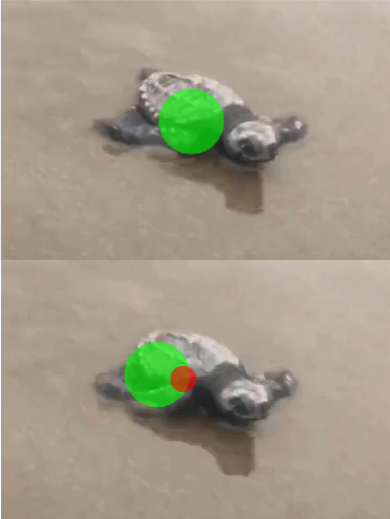

As funções `predict `e `correct` atualizam a *matriz de covariância de estado* do Filtro de Kalman (oh céus!), o que modela a cinemática do objeto. Elas atualizam o filtro mesmo sem um output. Tal pode ser chamado pela função `kf.StateCovariance`.

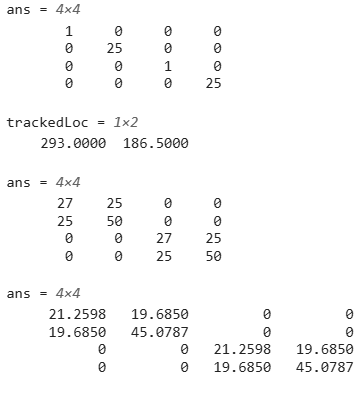

Aplicando um `while` possibilita a implementação do filtro em todo o vídeo como segue:

while(hasFrame(turtleVideo)==1)
    trackedLoc = predict(kf);

    frame = readFrame(turtleVideo);
    [bbox,score] = detect(detector,frame);
    bbox = bbox(score>95,:);
    score = score(score>95);

    if ~isempty(bbox)
        strongestBbox = selectStrongestBbox(bbox,score,NumStrongest=1);
        centroid = [strongestBbox(1)+strongestBbox(3)/2  strongestBbox(2)+strongestBbox(4)/2];
        frame = insertShape(frame,"filled-circle",[centroid 50],Color="green");
        trackedLoc = correct(kf,centroid);
    end

    frame = insertShape(frame,"filled-circle",[trackedLoc 20],Color="red");
    imshow(frame)
    drawnow
end

Adiciona-se um `if-end` para que não haja um erro por conta do sumiço da tartaruga. O `kf` vai continuar se atualizando